close all;
clear;

## Loading system parameters

parameters_maggy_V2;
% Define the point to linearize around
paramsFast = params;
correctionFactorFast = computeSolenoidRadiusCorrectionFactor(params,'fast');
paramsFast.solenoids.r = correctionFactorFast*paramsFast.solenoids.r;
[zEq, zEqInv, dzEq, dzEqInv] = computeSystemEquilibria(paramsFast,'fast');
xLp = [0,0,zEq(1),zeros(1,9)]'; % Linearizing around the equilibria
uLp = zeros(length(params.solenoids.r),1);

% Define the model to be used in linearization
modelName = 'fast';

% Setting up system equations with speficied model and parameters for
% simpler representation
f = @(x,u) maglevSystemDynamics(x,u,paramsFast,modelName);
h = @(x,u) maglevSystemMeasurements(x,u,paramsFast,modelName);

fprintf('Equilibria: ')

Equilibria: 

xLp

xLp =          0
         0
    0.0365
         0
         0
         0
         0
         0
         0
         0


## Linearization

Linearization is an important tool for analyzing stability and designing linear controllers for nonlinear systems. Here, we see how to linearize the maglev system.

% Define the point to linearize around
xLp = [0,0,zEq(1),zeros(1,9)]'; % Linearizing around the equilibria
uLp = zeros(length(params.solenoids.r),1);

% Linearization
delta = 1e-6; % Step-size used in numerical linearization
[A,B,C,D] = finiteDifferenceLinearization(f,h,xLp,uLp,delta);

fprintf('Size of A: %.f, %.f\n', size(A))

Size of A: 12, 12


fprintf('Size of B: %.f, %.f\n', size(B))

Size of B: 12, 4


fprintf('Size of C: %.f, %.f\n', size(C))

Size of C: 9, 12


fprintf('Size of D: %.f, %.f\n', size(D))

Size of D: 9, 4


## LQR control

Using the linearized model from above, we can define a simple LQR controller in order to stabilize the system at the equilibrium.

### Designing LQR controller

The rotation around the center axis of the levitating magnet is uncontrollable. Thus, the rotation of the linear model is uncontrollable around the z-axis (since the axis of the magnet is parallel with it in the equilibrium). Luckily, we do not need to worry about this axis when controlling the system because it does not affect any of the other states in the linear model, so we may just remove them from the linear model when designing our controller:

% Defining reduced order system
I = [1:5,7:11];
Ared = A(I,I);
Bred = B(I,:);
Cred = C(:,I);
Dred = D(:,:);

% Cost matrices
Q = diag([1e6,1e6,1e2, 1e1,1e1, 1e2,1e2,1e2, 1e2,1e2]);
R = 1e-0*eye(length(params.solenoids.r));

% Computing LQR estimate
Kred = round(lqr(Ared,Bred,Q,R),3); % Rounding can sometimes be dangerous!

% increasing order of our controller for controlling the real system
K = [Kred(:,1:5), zeros(4,1), Kred(:,6:end), zeros(4,1)];


## **Load Policy Parameters or select Random Policy**

%f = @(x,u) maglevSystemDynamics_contrained_horizontal(x,u,paramsFast,modelName);

exploration = 0;
K_end = -1;

U_MAX = 50;
dt = 0.02

dt = 0.0200

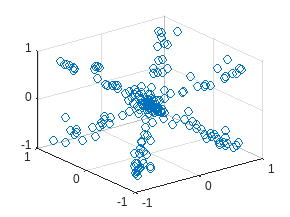

if exploration == 0
    policy_centers = table2array(readtable('policy/policy_centers.csv'));
    policy_f_linear_weight = table2array(readtable('policy/policy_f_linear.weight.csv'));
    W=policy_f_linear_weight;
    policy_log_lengthscales = table2array(readtable('policy/policy_log_lengthscales.csv'));
    policy_lengthscales = exp(policy_log_lengthscales');
    
    phi = @(x) [x(1:3)' x(7:12)' cos(x(4:6))' sin(x(4:6))']';
    figure
    scatter3(policy_centers(:,1), policy_centers(:,2), policy_centers(:,3))
end

k_rep = 0;

while K_end < 10
    if exploration > 0
        tf = 3.0
        %policy = @(x, t) - K*(x-xLp)-uLp;
        policy = @(x, t) 1 * t * sin(2*5*pi*t*ones(4,1)) - K*(x-xLp)-uLp;
        x0 = xLp + [0.004 -0.001 0.0 0 0 0 zeros(1, 6)]';
    else
        tf = 1

        u_max = U_MAX / (2^k_rep)
        
        policy = @(x, t) - K*(x-xLp)-uLp + u_max * tanh( W * exp(-sum( ((policy_centers-phi(x)')./policy_lengthscales').^2, 2)) / u_max);
        x0 = xLp; % + [randn(1,3)*0.0 zeros(1,9)]'
    
        
    end
    % Simulation
    tic
    % Initialize variables
    % Initial condition
    
    % Pre-allocate arrays to store results
    num_steps = round(tf / dt);    u_result = zeros(num_steps, 4);
    tSpan = linspace(0,tf,num_steps);
    
%     x_result = zeros(num_steps, 12);
%     u_result = zeros(num_steps, 4);
%     x_current = x0;
%     t_current = 0.0;
%     tic
%     for i = 1:num_steps
%         x_result(i, :) = x_current;
%         u = policy(x_current', t_current);
%         u_result(i, :) = u;
%         [t_out, x_out] = ode15s(@(t, x) f(x, u), [t_current t_current + dt], x_current);
%         t_current = t_out(end);
%         x_current = x_out(end, :) + + randn(1,12)*0.001; % measurement noise
%     end
    [t,x_result] = ode15s(@(t,x) f(x,policy(x,t)), tSpan, x0);
    
    
    for i=1:num_steps
        if x_result(i,3) < 0 || any(x_result(i,4:6)) > pi/3   % end simulation condition [To be optimized]
            K_end = i-2
            break
        end
        u_result(i,:) = policy(x_result(i,:)', tSpan(i)) -(- K*(x_result(i,:)'-xLp)-uLp);
        x_result(i,:) = x_result(i,:) + randn(1,12)*0.0002;
    end
    
    if K_end > 0
        u_result = u_result(1:K_end, :);
        x_result = x_result(1:K_end, :);
        tSpan = tSpan(1:K_end);
    else
        K_end = length(x_result(:,1))
    end
    
    fprintf('simulation time: %.2fs\n', toc)
    k_rep = k_rep + 1 ;
end

tf = 1

u_max = 50

K_end = 50

simulation time: 5.20s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

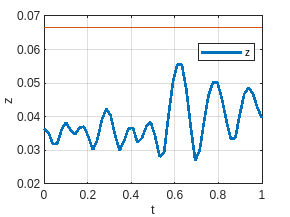

figure;
clf; grid on; hold on; box on;
plot(tSpan, x_result(:,3),'linewidth',2)
plot(tSpan, (zEq+0.03)*ones(length(tSpan),1))
legend({'z'},'location','best')
xlabel('t')
ylabel('z')

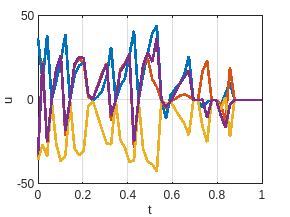


figure;
clf; grid on; hold on; box on;
plot(tSpan, u_result,'linewidth',2)
xlabel('t')
ylabel('u')

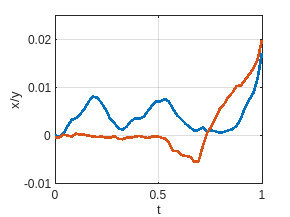



figure;
clf; grid on; hold on; box on;
plot(tSpan, x_result(:,1:2),'linewidth',2)
xlabel('t')
ylabel('x/y')

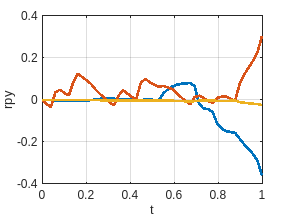


figure;
clf; grid on; hold on; box on;
plot(tSpan, x_result(:,4:6),'linewidth',2)
xlabel('t')
ylabel('rpy')

## Animation

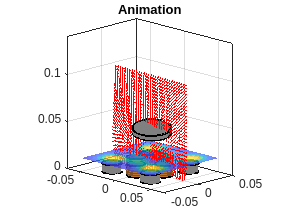

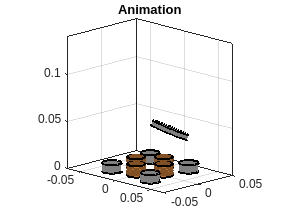

% Defining the plane(s) we want to evaluate the magnetic field
[X,Z] = meshgrid(linspace(-0.05,0.05,31));

% Figure setup
figure;
clf; grid on; hold on; box on; axis equal; view([45,15]);
title('Animation')
xlim([-0.07,0.07])
zlim([-0.07,0.07]+0.07)

plotBaseArtistic(params);
H = plotMagnetArtistic(0,0,0.05,0,0,0,params);
zMin = max([params.solenoids.z+params.solenoids.l/2, params.permanent.z+params.permanent.l/2]) + params.magnet.l/2; % Physical Limitations
zMax = 0.1; % Arbitrarily chosen

% Animation 
for i = 1:K_end
    % Compute & plot magnetic field
    u = policy(x_result(i,:)',0);
    [bx,by,bz] = computeFieldTotal(X,zeros(size(X)),Z+0.05,x_result(i,:)',u,params,'fast');

    NORM = sqrt(bx.^2 + by.^2 + bz.^2);
    
    bx = bx./NORM;
    by = by./NORM;
    bz = bz./NORM;

    try
        delete(hField);
    catch
    end
    hField = quiver3(X,zeros(size(X)),Z+0.05,bx,by,bz,'r');

    % Compute surface field
    [bx,by,bz] = computeFieldTotal(X,Z,zMin*ones(size(X)),x_result(i,:)',u,params,'fast');

    NORM = sqrt(bx.^2 + by.^2 + bz.^2);
    
    try
        delete(hSurf);
    catch   
    end
    hSurf = surf(X,Z,1e-6*NORM+zMin,NORM,'faceAlpha',0.75,'EdgeColor','none');

    % Update magnet position
    updatePositionOfObject(H,x_result(i,1),x_result(i,2),x_result(i,3),x_result(i,4),x_result(i,5),x_result(i,6));
    drawnow;
end

## **Save data**

writematrix(x_result, 'policy/noisy_samples.csv')
writematrix(u_result, 'policy/input_samples.csv')